## 1)

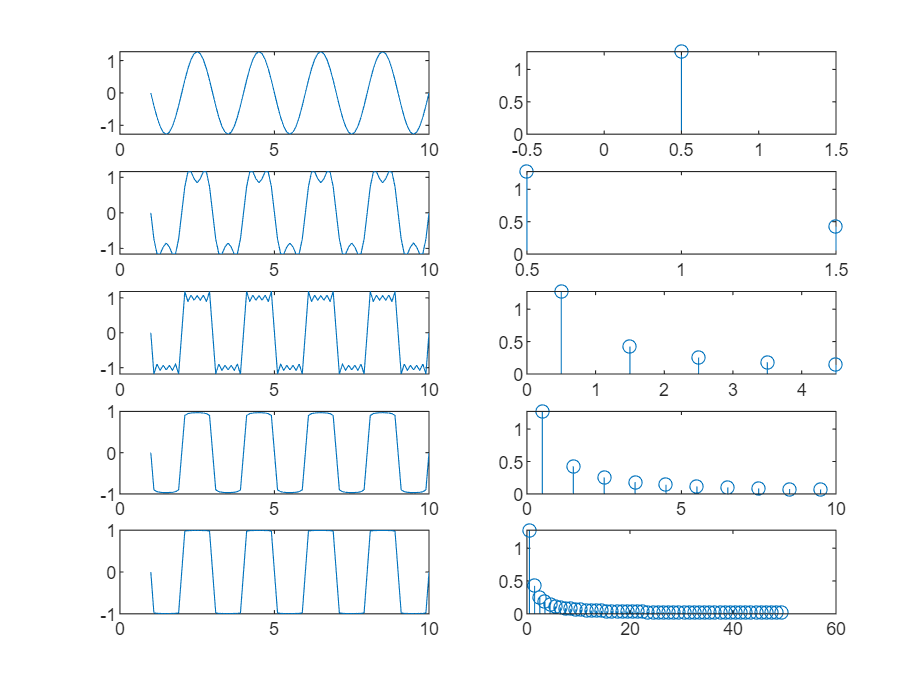

t=1:0.1:10;
% for i=1:length(t)
% y=4/(t(i)*pi);
% end
% plot(t,y);
A=1;
T=2;
w=(2*pi)/T;

subplot(5,2,1)
[~,coef,freq] = costam(A,t,w,1);
subplot(5,2,2)
stem(freq,coef);
subplot(5,2,3)
[~,coef,freq] = costam(A,t,w,3);
subplot(5,2,4)
stem(freq,coef);
subplot(5,2,5)
[~,coef,freq] = costam(A,t,w,10);
subplot(5,2,6)
stem(freq,coef);
subplot(5,2,7)
[~,coef,freq] = costam(A,t,w,20);
subplot(5,2,8)
stem(freq,coef);
subplot(5,2,9)
[y,coef,freq] = costam(A,t,w,100);
subplot(5,2,10)
stem(freq,coef);

## 2)

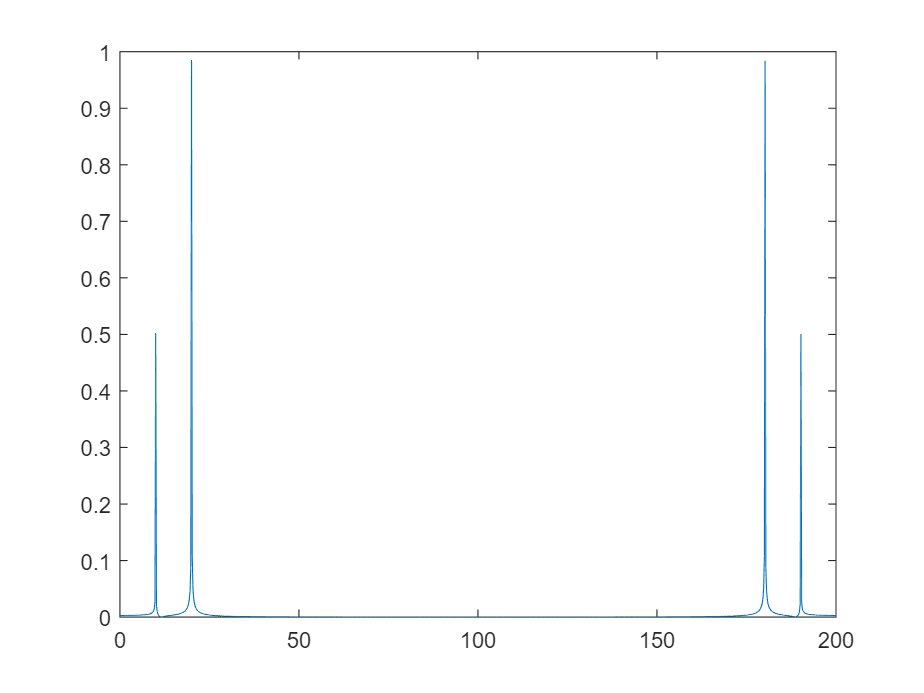

clear;
N=1001;
fs=200;
dt=1/fs;
df=fs/(N-1);
n=0;
f=df*(0:N-1);
t=dt*(0:N-1);
x = cos(2*pi*10*t)+2*cos(2*pi*20*t);

y=fft(x);
m=abs(y)/N;
p=rad2deg(unwrap(angle(y)));
figure(2);
plot(f,m);

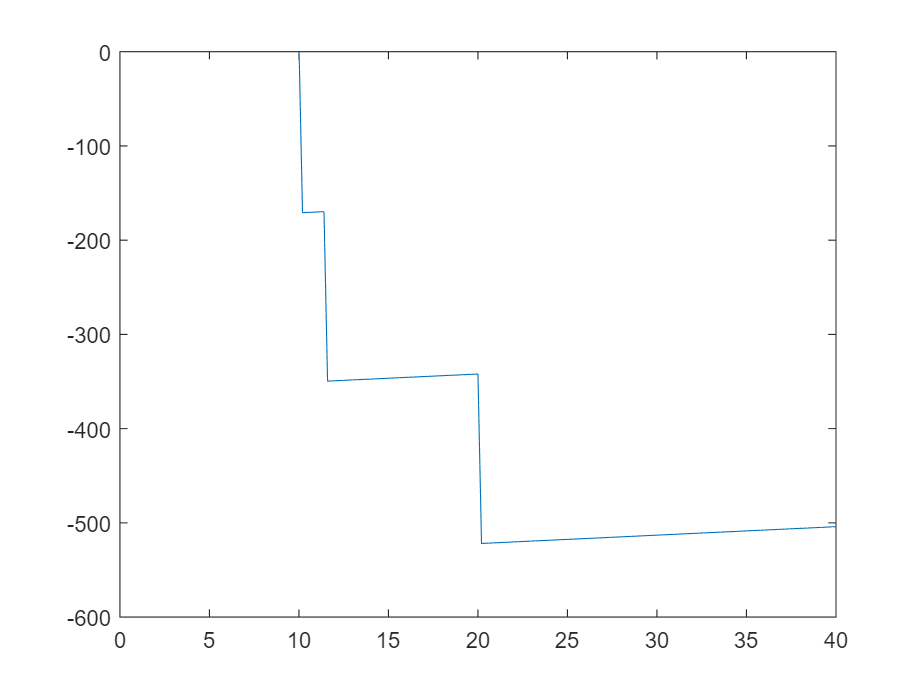

plot(f,p);
xlim([0 40]);
ylim([-600 0])